Задание 1

net = network % пустая нейронная сеть

net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 0
         numLayers: 0
        numOutputs: 0
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: []
      inputConnect: []

Задание 2.

Создать объект класса нейронной сети network, и вывести на экран все поля и все ячейки этого объекта, а также его графический образ.

net = network(2,3,[1;0;0],[1 1;0 0;0 0],[0 0 0;1 0 0;0 1 0],[0 0 1]);

disp(net) % поля и ячейки

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 2
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 0; 0]
      inputConnect: [1

view(net)

Задание 3

gensim(net)

GENSIM: Input 1 has been pruned.
GENSIM: Input 2 has been pruned.
GENSIM: Layer 1 has been pruned.
GENSIM: Layer 2 has been pruned.
GENSIM: Layer 3 has been pruned.
GENSIM: Output 1 has been pruned.
GENSIM: Generated Simulink neural network has no outputs.


ans = 'untitled1'

Задание 4.

Создать вычислительную модель нейронной сети с тремя входами, двумя слоями и одним целевым выходом, используя общий конструктор сети с параметрами network.

Связи между слоями должны быть только прямыми, входы необходимо соединить с первым слоем, выход второго слоя должен быть выходом сети. Только второй слой должен иметь смещения. 

Слои должны иметь функции активации purelin и hardlim соответственно.

% Создание нейронной сети
net = network(3,2,[0;1],[1 1 1;0 0 0],[0 0; 1 0],[0 1]);

% Установка функций активации для слоев
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'hardlim';

view(net)

Задание 5.

Построить графики всех функций активации, применяемые в MATLAB Neural Network.

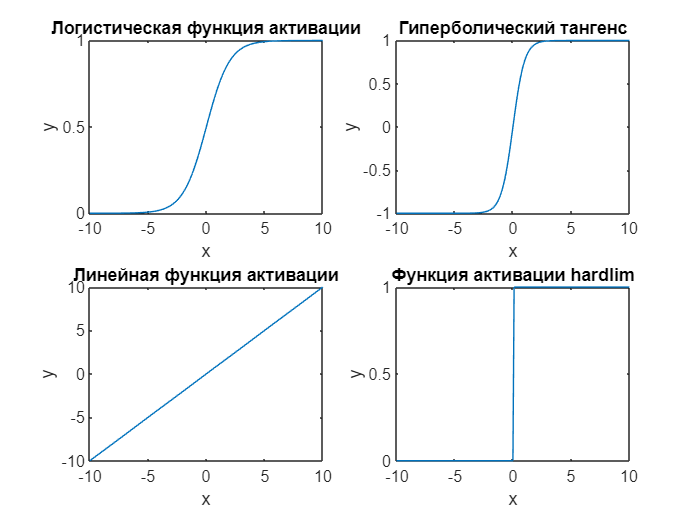

% https://medium.com/analytics-vidhya/introduction-to-various-activation-functions-using-matlab-r2017b-part-1-6ccb4228cb5
x = -10:0.1:10;


y_logsig = 1 ./ (1 + exp(-x)); 
y_tanh = tanh(x);
y_purelin = x; 
y_hardlim = (x > 0); 

figure
subplot(2,2,1)
plot(x, y_logsig)
title('Логистическая функция активации')
xlabel('x')
ylabel('y')

subplot(2,2,2)
plot(x, y_tanh)
title('Гиперболический тангенс')
xlabel('x')
ylabel('y')

subplot(2,2,3)
plot(x, y_purelin)
title('Линейная функция активации')
xlabel('x')
ylabel('y')

subplot(2,2,4)
plot(x, y_hardlim)
title('Функция активации hardlim')
xlabel('x')
ylabel('y')

Задание 6.

1) разработать структурную схему однослойной нейронной сети пользователя;

2) определить параметры созданной нейронной сети (веса и смещение) и проверить правильность работы сети для последовательности входных векторов (не менее 5);

3) переустановить значения матриц весов и смещений;

4) проверить работу сети.

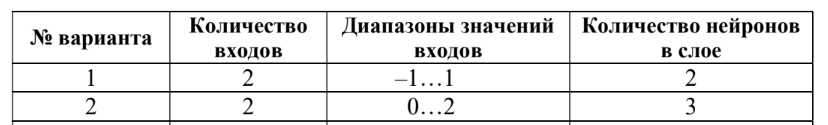

net = network(2,1,1,[1 1],[0],[1]);
net.inputs{:}.size = 1;
net.inputs{:}.range = [0 2];
net.layers{1}.size=3;
net.layers{1}.transferFcn = 'purelin';
view(net)

net.IW{1,1} = [2; 1; 3];
net.IW{1,2} = [-1; 3; 4];
net.b{1} = [1;1;-1];

inputs = [1; 0];
sim(net,inputs)

ans =      3
     2
     2


purelin(2*inputs(1)-1*inputs(2)+1)

ans = 3

purelin(1*inputs(1)+3*inputs(2)+1)

ans = 2

purelin(3*inputs(1)+4*inputs(2)-1)

ans = 2


inputs = [1; -1];
sim(net,inputs)

ans =      4
    -1
    -2


purelin(2*inputs(1)-1*inputs(2)+1)

ans = 4

purelin(1*inputs(1)+3*inputs(2)+1)

ans = -1

purelin(3*inputs(1)+4*inputs(2)-1)

ans = -2


inputs = [0; 2];
sim(net,inputs)

ans =     -1
     7
     7


purelin(2*inputs(1)-1*inputs(2)+1)

ans = -1

purelin(1*inputs(1)+3*inputs(2)+1)

ans = 7

purelin(3*inputs(1)+4*inputs(2)-1)

ans = 7


inputs = [-0.3; 0.1];
sim(net,inputs)

ans =     0.3000
    1.0000
   -1.5000


purelin(2*inputs(1)-1*inputs(2)+1)

ans = 0.3000

purelin(1*inputs(1)+3*inputs(2)+1)

ans = 1

purelin(3*inputs(1)+4*inputs(2)-1)

ans = -1.5000


inputs = [1; -0.4];
sim(net,inputs)

ans =     3.4000
    0.8000
    0.4000


purelin(2*inputs(1)-1*inputs(2)+1)

ans = 3.4000

purelin(1*inputs(1)+3*inputs(2)+1)

ans = 0.8000

purelin(3*inputs(1)+4*inputs(2)-1)

ans = 0.4000

Задание 7.

1) разработать структурную схему нейронной сети пользователя;

2) определить параметры созданной нейронной сети (веса и смещение);

3) проверить работу сети;

4) выполнить непосредственный и сравнить полученные результаты.

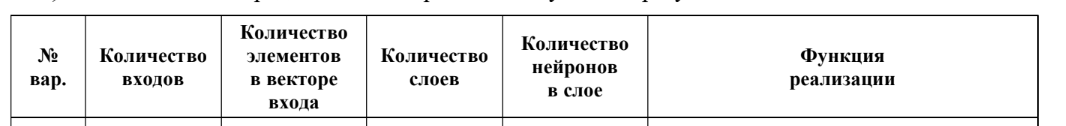

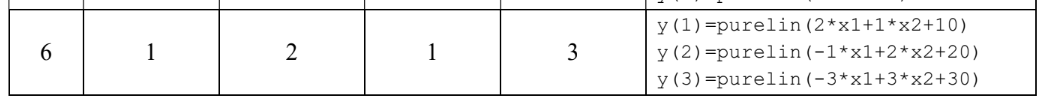

net = network(1,1,1,[1],[0],[1]);
net.inputs{1}.size = 2;
net.layers{1}.size=3;
net.layers{1}.transferFcn = 'purelin';
view(net)

net.b{1}(1) = 10;
net.b{1}(2) = 20;
net.b{1}(3) = 30;

net.IW{1,1} = [2 1; -1 2; -3 3];  
%gensim(net)

% Проверка работы сети
inputs = [1; 2];
sim(net, inputs)

ans =     14
    23
    33


% Непосредственное выполнение функций активации
inputs = [1; 2];
outputs = [2*inputs(1) + 1*inputs(2) + 10; -1*inputs(1) + 2*inputs(2) + 20; -3*inputs(1) + 3*inputs(2) + 30];
disp(outputs);

    14
    23
    33



inputs = [-1; 10];
sim(net, inputs)

ans =     18
    41
    63


outputs = [2*inputs(1) + 1*inputs(2) + 10; -1*inputs(1) + 2*inputs(2) + 20; -3*inputs(1) + 3*inputs(2) + 30];
disp(outputs);

    18
    41
    63



inputs = [-10; 23];
sim(net, inputs)

ans =     13
    76
   129


outputs = [2*inputs(1) + 1*inputs(2) + 10; -1*inputs(1) + 2*inputs(2) + 20; -3*inputs(1) + 3*inputs(2) + 30];
disp(outputs);

    13
    76
   129



Задание 8.

Для простого нейрона с одним входом p и функцией активации hardlim подобрать весовой коэффициент W и смещение b таким образом, чтобы обеспечить инвертирование входного сигнала, т. е. замену нуля единицей, а единицы нулем.

net = network(1,1,1,[1],[0],[1]);
net.inputs{1}.size = 1;
net.layers{1}.size=1;
net.layers{1}.transferFcn = 'hardlim';
view(net)

net.IW{1,1}(1) = [-1];
net.b{1}(1) = 0.5;

p = 0;
sim(net, p)

ans = 1


p = 1;
sim(net, p)

ans = 0

Задание 9.

Создать однослойную сеть с двумя входами р1 и р2 и функцией активации hardlim, подобрать весовые коэффициенты и смещение таким образом, чтобы сеть выполняла функции: а) логического сложения, б) логического умножения, в) логического сложения и логического умножения.

a)

net = network(2,1,1,[1 1],[0],[1]);
net.inputs{1}.size = 1;
net.inputs{2}.size = 1;
net.layers{1}.size=1;
net.layers{1}.transferFcn = 'hardlim';
view(net)

net.IW{1,1} = [1];
net.IW{1,2} = [1];
net.b{1}(1) = -0.5;

p1 = [0 0 1 1; 0 1 0 1]

p1 =      0     0     1     1
     0     1     0     1



sim(net, p1)

ans =      0     1     1     1



% p1 = 1;
% p2 = 1;
% sim(net, [p1;p2])
% 
% p1 = 0;
% p2 = 0;
% sim(net, [p1;p2])
% 
% p1 = 1;
% p2 = 0;
% sim(net, [p1;p2])

в)

net = network(2,1,1,[1 1],[0],[1]);
net.inputs{1}.size = 1;
net.inputs{2}.size = 1;
net.layers{1}.size=2;
net.layers{1}.transferFcn = 'hardlim';
view(net)

net.IW{1,1} = [1; 1];
net.IW{1,2} = [1; 1];
net.b{1} = [-0.5; -1.5];

p1 = [0 0 1 1; 0 1 0 1]

p1 =      0     0     1     1
     0     1     0     1



sim(net, p1)

ans =      0     1     1     1
     0     0     0     1


Задание 10.

Используя конструктор класса network с параметрами и операторы присваивания для полей и ячеек объектов этого класса, построить, выдать на экран и промоделировать искусственные нейронные сети следующей архитектуры:

b) трехслойная сеть с прямой передачей сигналов и с тремя нейронами в каждом слое; количество входов – три с двумя, одним и тремя компонентами соответственно, подается на первый слой сети; для всех слоев имеется смещение; целевой выход – выход последнего слоя;

net = network(3,3,[1; 1; 1],[1 1 1; 0 0 0; 0 0 0],[0 0 0; 1 0 0; 0 1 0],[0 0 1]);

net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';

net.inputs{1}.size = 2;
net.inputs{2}.size = 1;
net.inputs{3}.size = 3;

net.layers{:}.size=3;
view(net)

% net.b{1} = [1;0;1];
% net.b{2} = [1;1;1];
% net.b{3} = [0;0;1];
% 
% net.IW{1,1} = [2 3; 4 3; 0 1];
% net.IW{1,2} = [-1;1;3];
% net.IW{1,3} = magic(3);


d) сеть с тремя слоями и тремя нейронами в каждом слое; три вектора входа подключаются по одному к каждому слою соответственно; имеется три выхода от всех слоев сети; смещения подключены к каждому слою;

net = network(3,3,[1; 1; 1],[1 0 0; 0 1 0; 0 0 1],[0 0 0; 0 0 0; 0 0 0],[1 1 1]);

net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';

net.layers{:}.size=3;
view(net)

% net.b{1} = [1;0;1];
% net.b{2} = [1;1;1];
% net.b{3} = [0;0;1];